# Advanced micro wave lab - experimants 1 and 2 

# Experimant 2

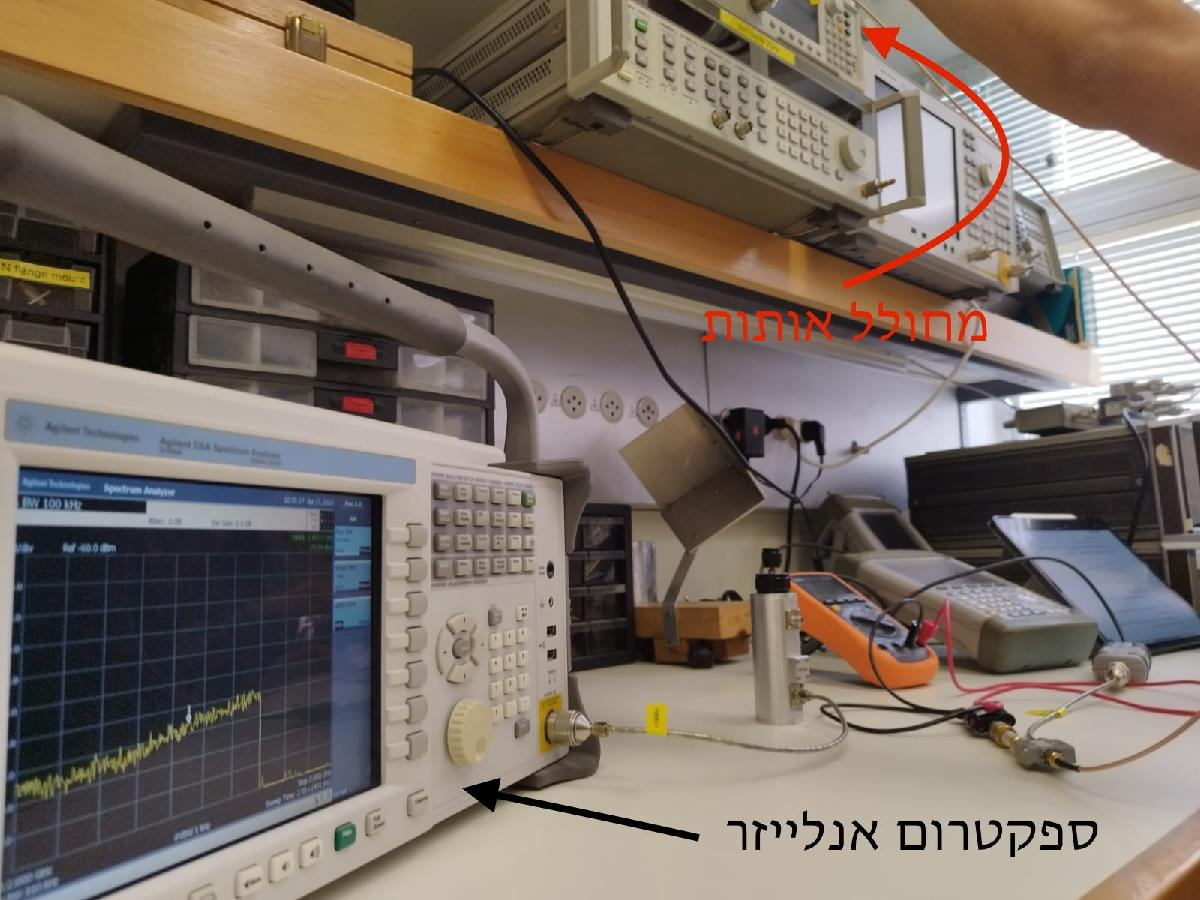

## 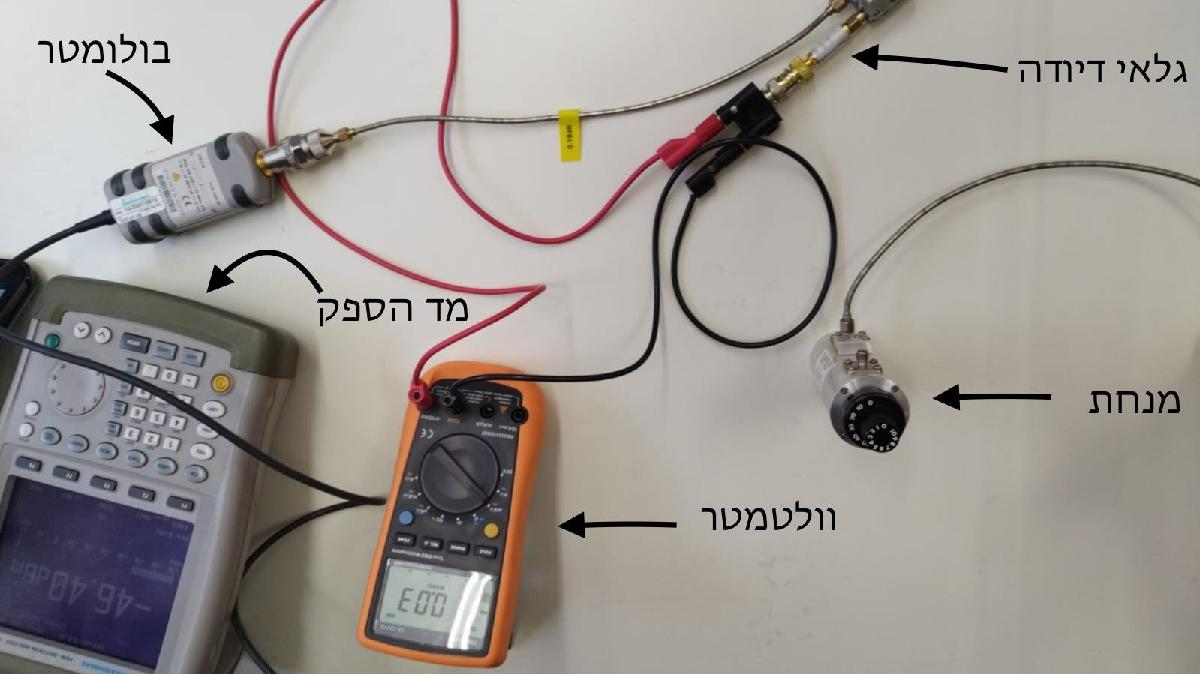

## Section 1 - measurements devices

measurements

power_dbm_input=[0.04,0.04,0.06,0.11,0.28,0.76,1.17,1.83,2.9,...	  
4.67,7.49,9.44,11.91,14.99,19.08,23.71]	;
power_dbm_output=[-46.3,-36.75,-31.85,-26.9,-21.89,-16.74,-14.4,...
-12.13,-10.12,-8.05,-6.06,-5.1,-4.11,-3.14,-2.08,-1.11];
Voltage_mV =[0.04,0.04,0.06,0.11,0.28,0.76,1.17,1.83,2.9,4.67,...
7.49,9.44,11.91,14.99,19.08,23.71];
T1 = table(power_dbm_input', power_dbm_output',Voltage_mV', 'VariableNames', {'Power dbm input', 'Power dbm output','Voltage mV'})

T1 = 16×3 table
    Power dbm input    Power dbm output    Voltage mV
    _______________    ________________    __________

          0.04               -46.3            0.04   
          0.04              -36.75            0.04   
          0.06              -31.85            0.06   
          0.11               -26.9            0.11   
          0.28              -21.89            0.28   
          0.76              -16.74            0.76   
          1.17               -14.4            1.17   
          1.83              -12.13            1.83   
           2.9              -10.12             2.9   
          4.67               -8.05            4.67   
          7.49               -6.06            7.49   
          9.44                -5.1            9.44   
         11.91               -4.11           11.91   
         14.99               -3.14           14.99   
         19.08   

Plot

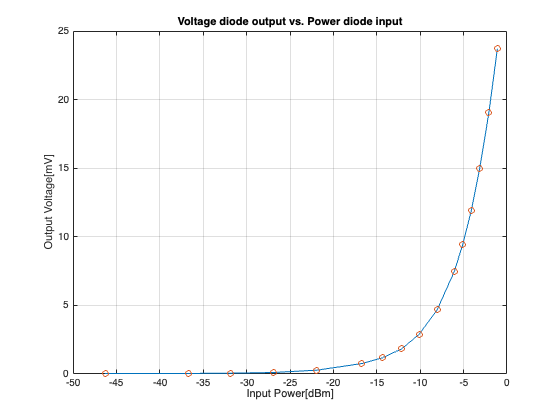

figure;
plot(power_dbm_output,Voltage_mV)
hold on 
scatter(power_dbm_output,Voltage_mV)
grid on 
title('Voltage diode output vs. Power diode input')
xlabel('Input Power[dBm]')
ylabel('Output Voltage[mV]')
saveas(gcf, '/Users/ohadformanair/Documents/Git/AML/LAB_1p2/Plots/VOlt_vs_power.png', 'png');

Exponential_fit(power_dbm_output, Voltage_mV)

ans =      General model Exp1:
     ans(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       30.78  (30.55, 31.01)
       b =      0.2316  (0.2292, 0.2339)

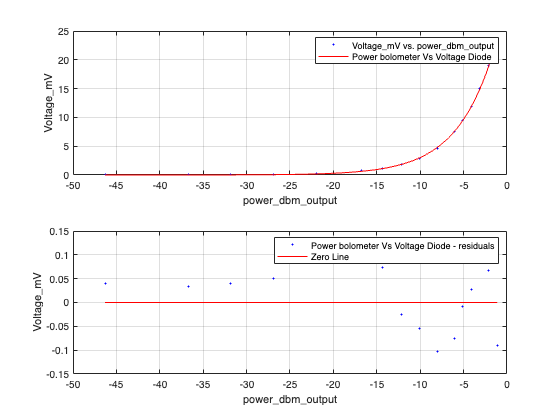

saveas(gcf, '/Users/ohadformanair/Documents/Git/AML/LAB_1p2/Plots/V_vs_P.png', 'png');

Fitareaof2nd(power_dbm_output, Voltage_mV)

ans =      General model:
     ans(x) = (b*x-a)^(2)+3
     Coefficients (with 95% confidence bounds):
       a =          -5  (fixed at bound)
       b =         0.5  (fixed at bound)

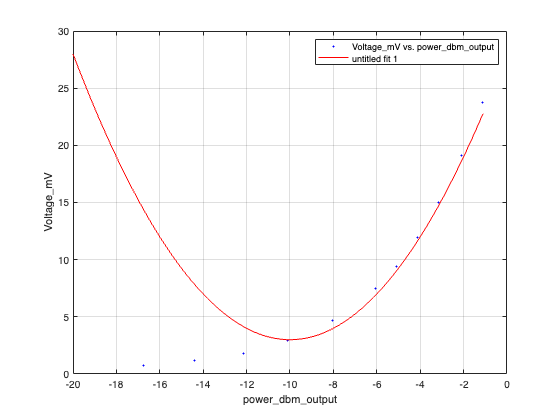

xlim([-20,0])

## Section 2 - Noise Vs RBW

RBW

RBW = [1e3,10e3,100e3,510e3,1e6,5e6];
noise_level = [-80.13,-78.9,-77.56,-75.88,-72.72,-66];
T2 = table(RBW', noise_level', 'VariableNames', {'RBW', 'Noise_Level'})

T2 = 6×2 table
      RBW      Noise_Level
    _______    ___________

       1000      -80.13   
      10000       -78.9   
      1e+05      -77.56   
    5.1e+05      -75.88   
      1e+06      -72.72   
      5e+06         -66   


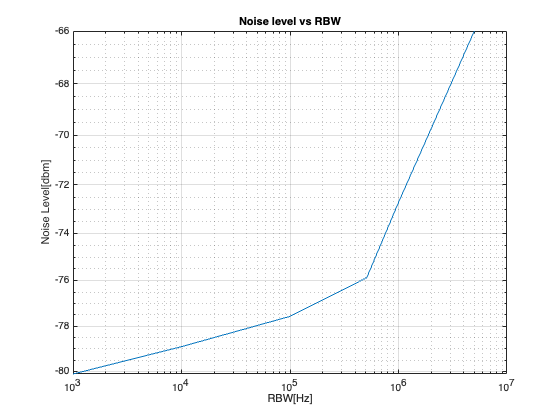

figure;
loglog(RBW,noise_level)
xlabel('RBW[Hz]')
ylabel('Noise Level[dbm]')
title('Noise level vs RBW')
grid on
saveas(gcf, '/Users/ohadformanair/Documents/Git/AML/LAB_1p2/Plots/Noise_vs_DBW.png', 'png');

# Experimant 1

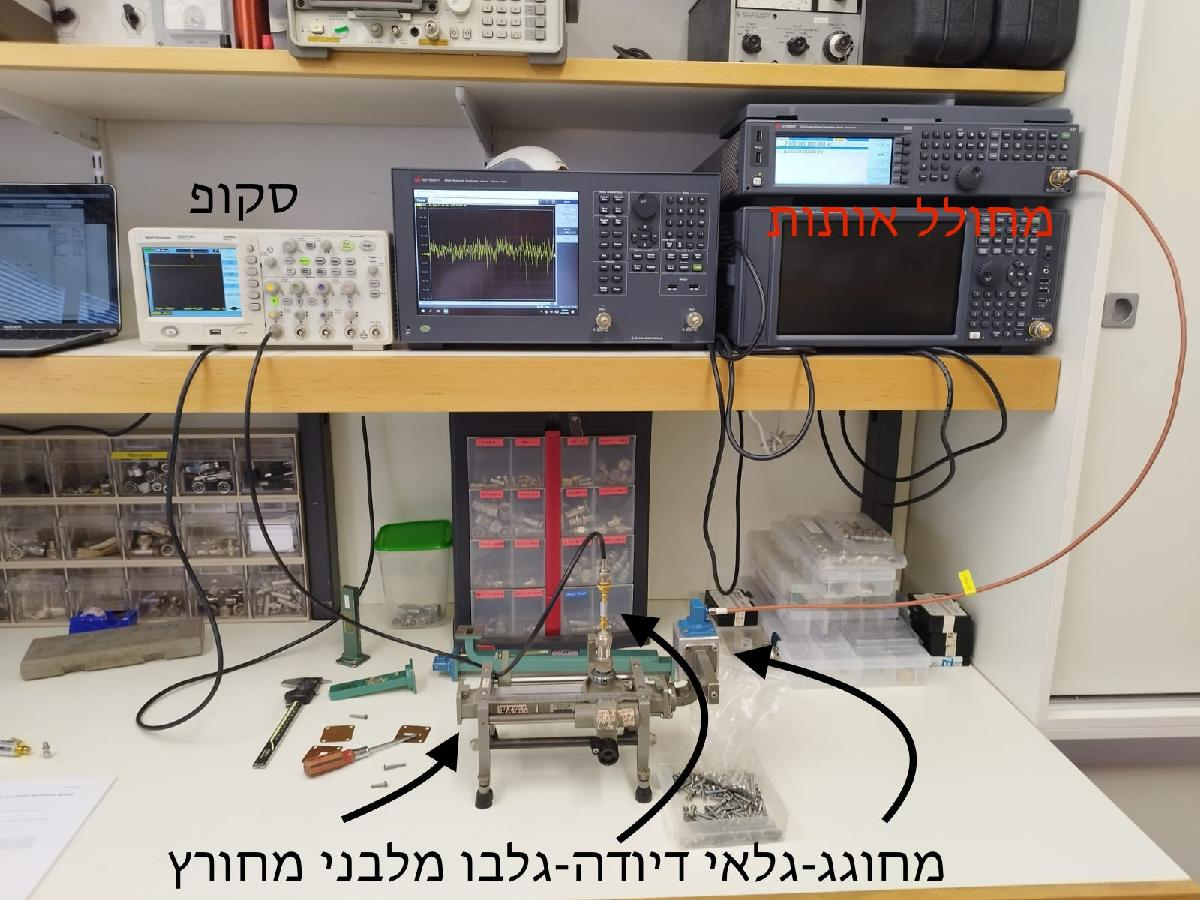

`wave guide dimensions - a=22.68 b=9.93`

## **Section 1 - loads, wave patterns **

Length = [8.5,9.5,10.5,11.5,12.5,13.5,14.5,15.5,16.5,17.5,18.5];
Capacity_voltage_mv=[-2.48,-3.24,-5.1,-2.45,-3.17,-5.17,-2.33,-3.12,-5.16,-2.4,-3.27];
cap_power = Volt_to_power(Capacity_voltage_mv);
Inductance_voltage_mv = [-5.38,-19,-4.86,-6,-19.1,-5.15,-5.94,-19.3,-5.01,-5.84,-19.1];
Inductance_power = Volt_to_power(Inductance_voltage_mv);
short_voltage_mv = [-0.95,-10.7,-6.3,-0.8,-10.8,-6.41,-0.91,-10.9,-6.42,-0.96,-10.7];
short_power = Volt_to_power(short_voltage_mv);
short_voltage_mv_8Ghz=[-19.8,-5.33,-4.77,-18.9,-11.8,-1.51,-15.2,-17.6,-1.43,-10,-19.9];
short8Ghz_power = Volt_to_power(short_voltage_mv_8Ghz);
Open_voltage_mv =[-3.1,-3.03,-4.76,-3.1,-3,-4.78,-3.12,-2.95,-4.73,-3.05,-2.94];
Open_power = Volt_to_power(Open_voltage_mv);
matched_voltage_mv =[-3.9,-4.2,-4.27,-3.88,-4.22,-4.26,-3.89,-4.2,-4.26,-3.91,-4.12];
matched_power = Volt_to_power(matched_voltage_mv);
T3 = table(Length', Capacity_voltage_mv',Inductance_voltage_mv',short_voltage_mv',...
    short_voltage_mv_8Ghz',Open_voltage_mv',matched_voltage_mv', 'VariableNames', {'Length', 'Capacity_voltage_mv',...
    'Inductance_voltage_mv','short_voltage_mv','short_voltage_mv_8Ghz','Open_voltage_mv','matched_voltage_mv'})

T3 = 11×7 table
    Length    Capacity_voltage_mv    Inductance_voltage_mv    short_voltage_mv    short_voltage_mv_8Ghz    Open_voltage_mv    matched_voltage_mv
    ______    ___________________    _____________________    ________________    _____________________    _______________    __________________

      8.5            -2.48                   -5.38                 -0.95                  -19.8                  -3.1                -3.9       
      9.5            -3.24                     -19                 -10.7                  -5.33                 -3.03                -4.2       
     10.5             -5.1                   -4.86                  -6.3                  -4.77                 -4.76               -4.27       
     11.5           

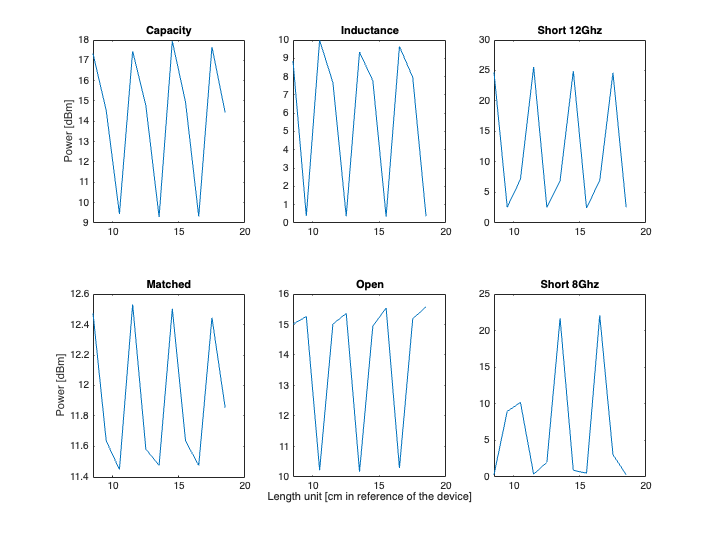

% Set the figure size
fig = figure('Position', [100 100 800 600]);

% Create subplots
subplot(2,3,1);
plot(Length,cap_power)
title('Capacity')
ylabel('Power [dBm]')
subplot(2,3,2);
plot(Length,Inductance_power)
title('Inductance')
subplot(2,3,3);
plot(Length,short_power)
title('Short 12Ghz')
subplot(2,3,4);
plot(Length,matched_power)
title('Matched')
ylabel('Power [dBm]')
subplot(2,3,5);
plot(Length,Open_power)
title('Open')
xlabel('Length unit [cm in reference of the device]')
subplot(2,3,6);
plot(Length,short8Ghz_power)
title('Short 8Ghz')
saveas(gcf, '/Users/ohadformanair/Documents/Git/AML/LAB_1p2/Plots/Wave_guide_loads.png', 'png');

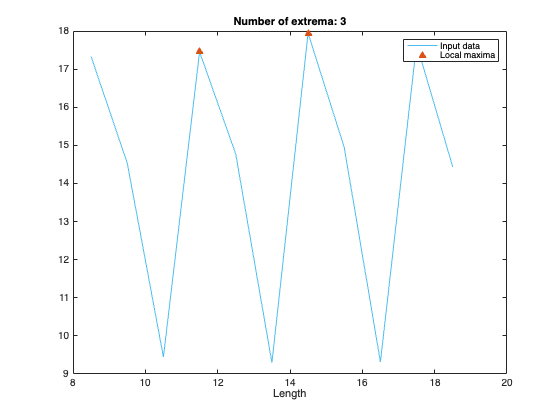

% Find local maxima
cap_maxima = islocalmax(cap_power,"SamplePoints",Length);

% Display results
figure
plot(Length,cap_power,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(Length(cap_maxima),cap_power(cap_maxima),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(cap_maxima))
hold off
legend
xlabel("Length")

wave_length_cap = diff(Length(cap_maxima))

wave_length_cap =      3     3


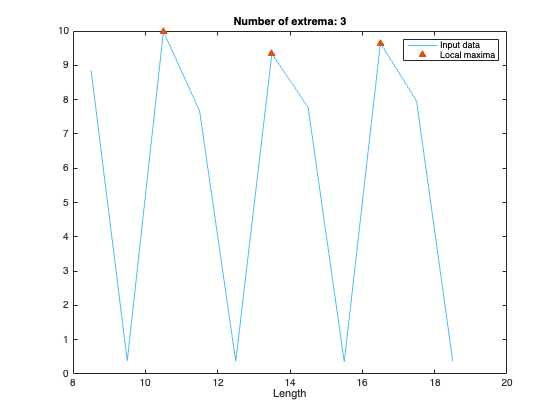

% Find local maxima
Ind_maxima = islocalmax(Inductance_power,"SamplePoints",Length);

% Display results
figure
plot(Length,Inductance_power,"Color",[77 190 238]/255,...
    "DisplayName","Input data")
hold on

% Plot local maxima
plot(Length(Ind_maxima),Inductance_power(Ind_maxima),"^",...
    "Color",[217 83 25]/255,"MarkerFaceColor",[217 83 25]/255,...
    "DisplayName","Local maxima")
title("Number of extrema: " + nnz(Ind_maxima))
hold off
legend
xlabel("Length")

wave_length_Ind = diff(Length(Ind_maxima))

wave_length_Ind =      3     3


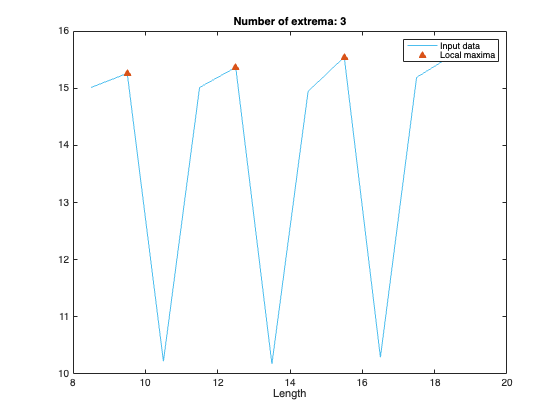

% Find local maxima
Open_maxima = islocalmax(Open_power,"SamplePoints",Length);

% Display results
figure
plot(Length,Open_power,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(Length(Open_maxima),Open_power(Open_maxima),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(Open_maxima))
hold off
legend
xlabel("Length")

wave_length_Open = diff(Length(Open_maxima))

wave_length_Open =      3     3


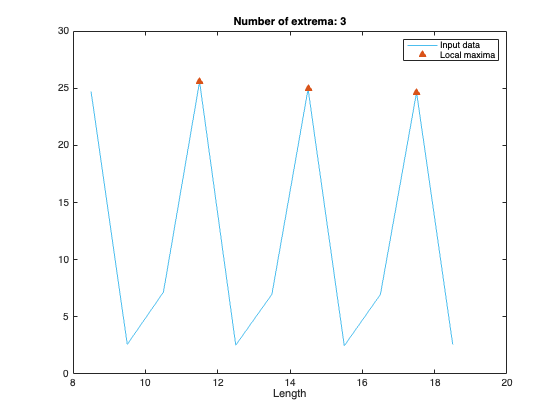

% Find local maxima
Short_maxima = islocalmax(short_power,"SamplePoints",Length);

% Display results
figure
plot(Length,short_power,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(Length(Short_maxima),short_power(Short_maxima),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(Short_maxima))
hold off
legend
xlabel("Length")

wave_length_short = diff(Length(Short_maxima))

wave_length_short =      3     3


Fit

figure;
Sine_sum_fit(Length,Capacity_voltage_mv)

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =       9.754  (-2.51e+05, 2.51e+05)
       b1 =      0.1232  (-508.7, 508.9)
       c1 =        2.92  (-7398, 7404)
       a2 =       6.196  (-2.51e+05, 2.51e+05)
       b2 =      0.1581  (-634.4, 634.7)
       c2 =       5.554  (-9226, 9237)
       a3 =       1.606  (1.378, 1.833)
       b3 =       2.099  (2.047, 2.151)
       c3 =       8.068  (7.342, 8.795)

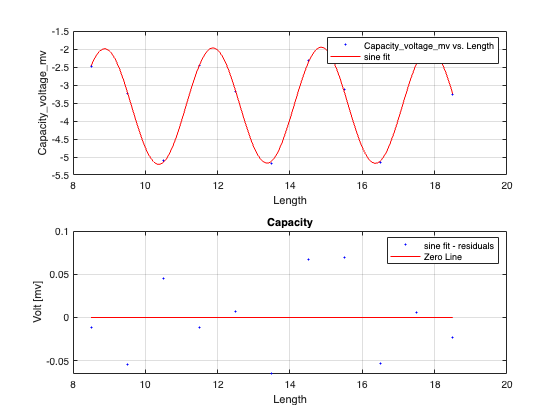

title('Capacity')
ylabel('Volt [mv]')

figure;
Sine2sum(Length,Inductance_voltage_mv)

ans =      General model Sin2:
     ans(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =       10.13  (10, 10.26)
       b1 =     0.05404  (0.0352, 0.07287)
       c1 =       3.929  (3.684, 4.174)
       a2 =       9.177  (9.056, 9.299)
       b2 =       2.095  (2.09, 2.099)
       c2 =      -2.565  (-2.631, -2.499)

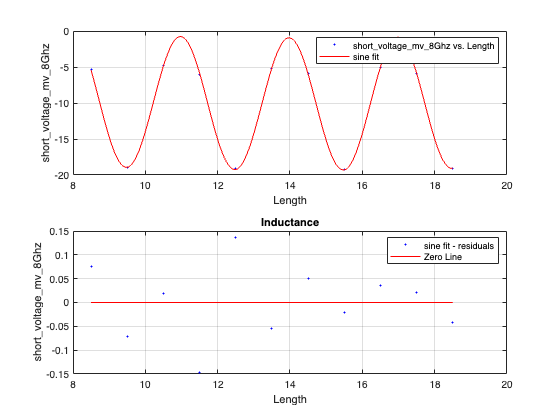

title('Inductance')

figure;
Sine_sum_fit(Length,short_voltage_mv)

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =       995.6  (-7.95e+11, 7.95e+11)
       b1 =       0.171  (-6.567e+04, 6.567e+04)
       c1 =       3.419  (-1.375e+06, 1.375e+06)
       a2 =       992.1  (-7.95e+11, 7.95e+11)
       b2 =      0.1711  (-6.643e+04, 6.643e+04)
       c2 =       6.564  (-1.349e+06, 1.349e+06)
       a3 =       5.121  (0.6486, 9.592)
       b3 =       2.101  (1.758, 2.444)
       c3 =       9.318  (4.626, 14.01)

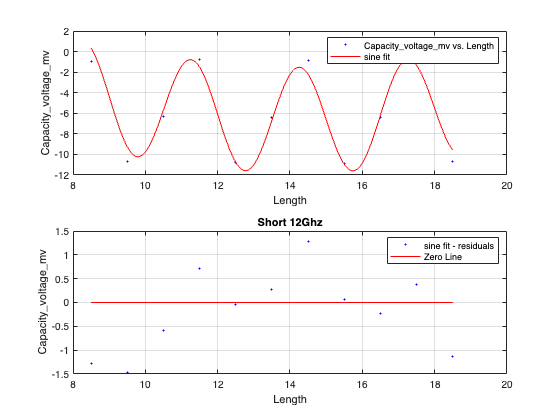

title('Short 12Ghz')

figure;
Sine_sum_fit(Length,matched_voltage_mv)

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =       14.17  (-8.735e+04, 8.738e+04)
       b1 =      0.1601  (-106.2, 106.5)
       c1 =       2.653  (-1364, 1370)
       a2 =       10.05  (-8.735e+04, 8.737e+04)
       b2 =      0.1917  (-126.8, 127.2)
       c2 =       5.388  (-1627, 1638)
       a3 =       0.222  (0.1522, 0.2917)
       b3 =       2.092  (1.951, 2.233)
       c3 =       8.775  (6.954, 10.6)

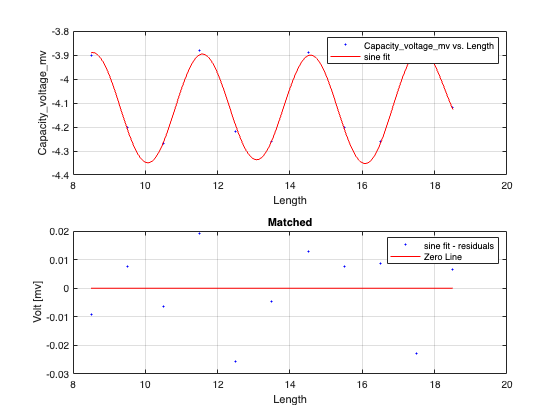

title('Matched')
ylabel('Volt [mv]')

figure;
Sine_sum_fit(Length,Open_voltage_mv)

ans =      General model Sin3:
     ans(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3)
     Coefficients (with 95% confidence bounds):
       a1 =        7.86  (-9.872e+05, 9.872e+05)
       b1 =     0.09389  (-2312, 2313)
       c1 =       3.442  (-3.241e+04, 3.242e+04)
       a2 =       4.236  (-9.872e+05, 9.872e+05)
       b2 =      0.1255  (-3234, 3235)
       c2 =       6.142  (-4.499e+04, 4.5e+04)
       a3 =       1.141  (1.055, 1.226)
       b3 =       2.094  (2.048, 2.141)
       c3 =         7.8  (7.138, 8.462)

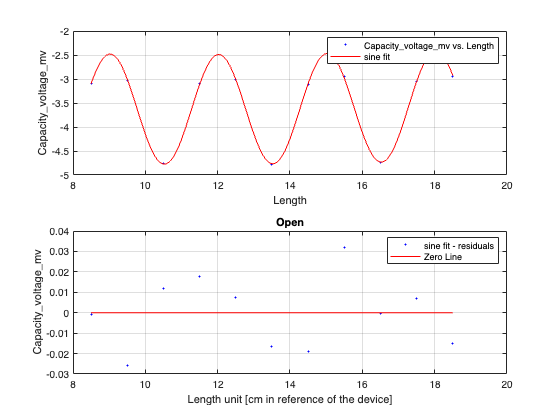

title('Open')
xlabel('Length unit [cm in reference of the device]')

figure;
Sine2sum(Length,short_voltage_mv_8Ghz)

ans =      General model Sin2:
     ans(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =       10.72  (10.14, 11.29)
       b1 =     0.03252  (-0.1153, 0.1803)
       c1 =       4.215  (2.431, 5.999)
       a2 =       9.523  (8.922, 10.12)
       b2 =       1.882  (1.858, 1.906)
       c2 =       1.519  (1.185, 1.854)

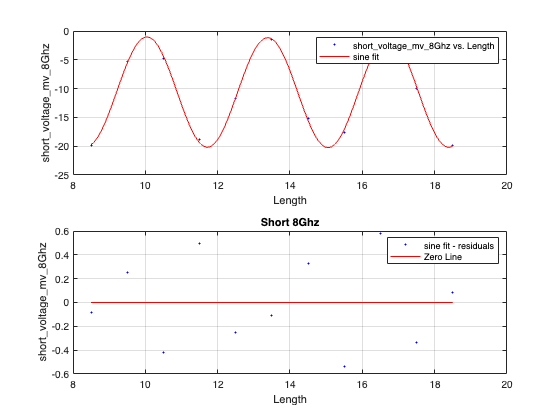

title('Short 8Ghz')

## Section 2 - Cutoff freq

Max_values_mv=[-20.4,-9.69,-15.8,-28,-70,-32.7,-1.12,-31.2,-1,-0.322,-0.400]

Max_values_mv =   -20.4000   -9.6900  -15.8000  -28.0000  -70.0000  -32.7000   -1.1200  -31.2000   -1.0000   -0.3220   -0.4000


freq_Ghz = [8,7.5,7,6.9,6.8,6.6,6.5,6.4,6,5.8,5.5]

freq_Ghz =     8.0000    7.5000    7.0000    6.9000    6.8000    6.6000    6.5000    6.4000    6.0000    5.8000    5.5000


T4 = table(freq_Ghz', Max_values_mv', 'VariableNames', {'freq_Ghz', 'Max_values_mv'})

T4 = 11×2 table
    freq_Ghz    Max_values_mv
    ________    _____________

        8           -20.4    
      7.5           -9.69    
        7           -15.8    
      6.9             -28    
      6.8             -70    
      6.6           -32.7    
      6.5           -1.12    
      6.4           -31.2    
        6              -1    
      5.8          -0.322    
      5.5            -0.4    


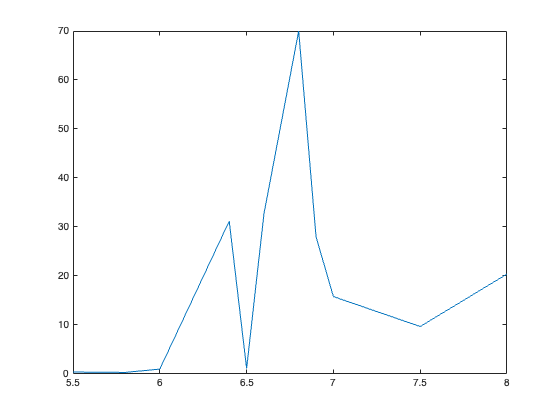

figure;
plot(freq_Ghz,abs(Max_values_mv))

## Functions

function P = Volt_to_power(Volt)
  a = 30.78;b=0.2316;
  P = a*exp(Volt*b); 
end